clc
clear all

% Symbolic variables
syms a fd fc fb k s

% Define the equations
eq1 = fd*sind(a)-(4/5)*fc == 0;
eq2 = -fd*cosd(a)+fb == 0;
eq3 = (3/5)*fc-90 == 0;

% Additional equation for fb = k * s
eq4 = fb - k*s == 0;

% Solve the system of equations
solutions = solve([eq1, eq2, eq3, eq4], [fd, fc, fb, s]);
disp('Solutions:')

Solutions:


disp(solutions)

    fd: [1×1 sym]
    fc: [1×1 sym]
    fb: [1×1 sym]
     s: [1×1 sym]



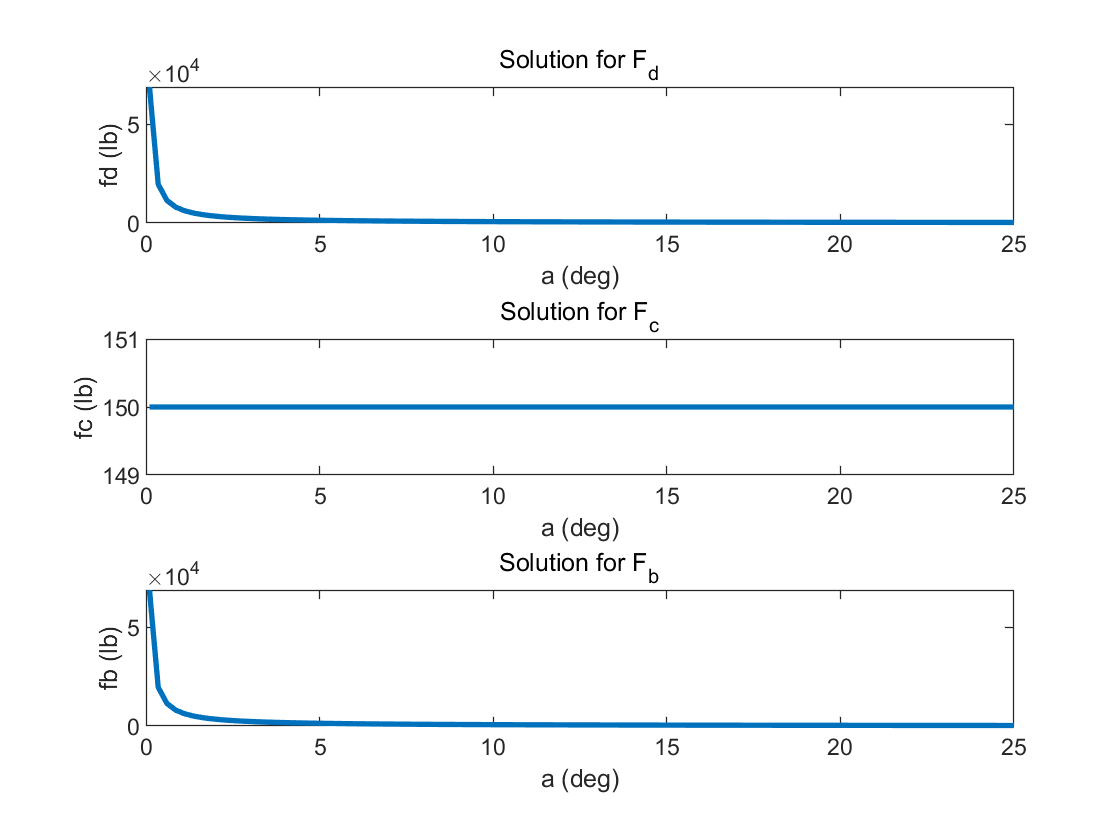


% Extract the symbolic expressions for fb, fc, and fd
% from the strcture
fb_solution = solutions.fb;
fc_solution = solutions.fc;
fd_solution = solutions.fd;
s_solution = solutions.s;

% Coordinates for plotting
a_values = linspace(0.1, 25, 100);
k_values = linspace(100, 500, 5);  
[a_grid, k_grid] = meshgrid(a_values, k_values);

% Evaluate the solutions for different values of x
fb_values = double(subs(fb_solution, a, a_values));
fc_values = double(subs(fc_solution, a, a_values));
fd_values = double(subs(fd_solution, a, a_values));

figure;

% Increase the font size of axis titles
ax = gca;
ax.FontSize = 14;
titleFontSize = 18;

subplot(3, 1, 1);
plot(a_values, fd_values, 'LineWidth', 2);
xlabel('a (deg)');
ylabel('fd (lb)');
title('Solution for F_d');

subplot(3, 1, 2);
plot(a_values, fc_values, 'LineWidth', 2);
xlabel('a (deg)');
ylabel('fc (lb)');
title('Solution for F_c');

subplot(3, 1, 3);
plot(a_values, fb_values,'LineWidth', 2);
xlabel('a (deg)');
ylabel('fb (lb)');
title('Solution for F_b');

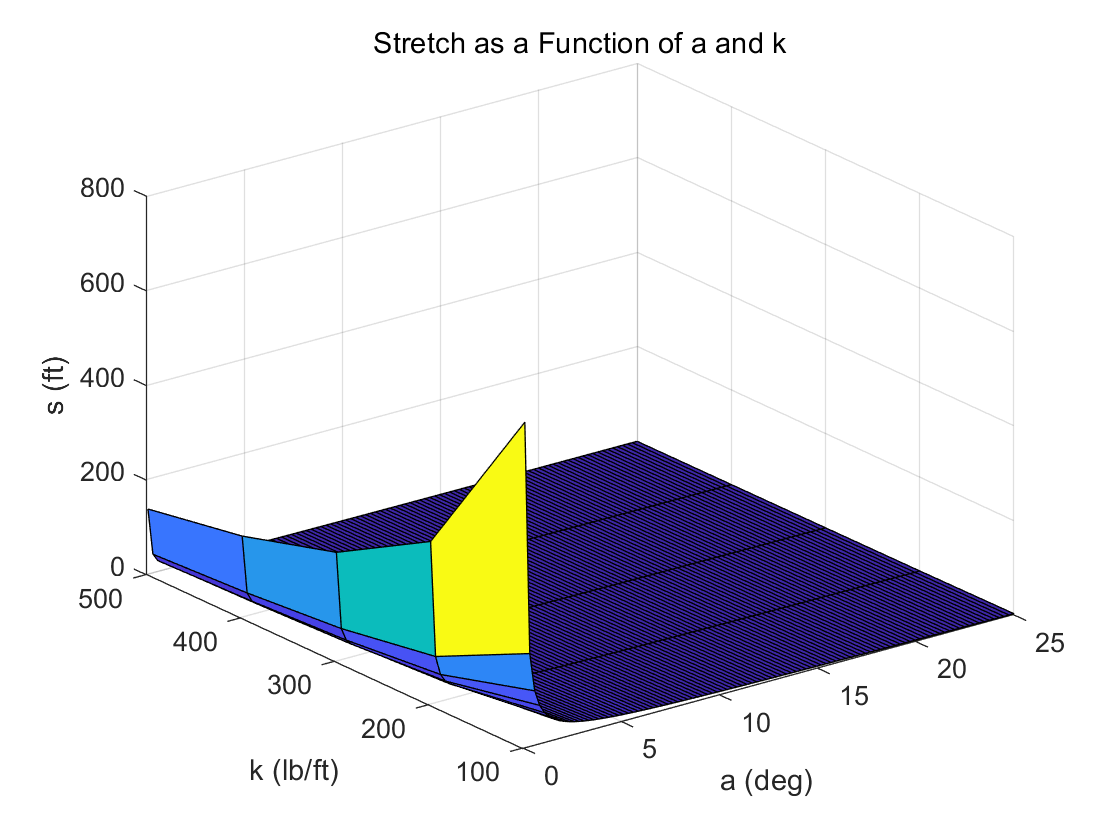


% Evaluate the symbolic expression for s over the grid
s_values = double(subs(s_solution, {a, k}, {a_grid, k_grid}));

% Create a 3D plot
figure;
surf(a_grid, k_grid, s_values);
xlabel('a (deg)');
ylabel('k (lb/ft)');
zlabel('s (ft)');
title('Stretch as a Function of a and k');